% Import data from text file
data = readtable("C:\Users\Lawrence Wontumi\Downloads\data.csv", "TextType", "string");

% Display results
data

data = 565×45 table
    timestamp_s    flight_t_s      dt_s       odom_x       odom_y        odom_z       odom_vx      odom_vy      odom_vz      odom_roll_rad    odom_pitch_rad    odom_yaw_rad    odom_rate_x_rad_s    odom_rate_y_rad_s    odom_rate_z_rad_s    imu_accel_x    imu_accel_y    imu_accel_z    imu_gyro_x    imu_gyro_y    imu_gyro_z    imu_temp_c    ref_x    ref_y      ref_z       ref_vx    ref_vy     ref_vz      thrust_cmd_n    thrust_cf    roll_rate_dps    <s

Step 1: Extract measurements

% Unwrap yaw to avoid artificial jumps
yaw = unwrap(data.odom_yaw_rad);

Z = [
    data.odom_x, data.odom_y, data.odom_z, ...
    data.odom_vx, data.odom_vy, data.odom_vz, ...
    data.odom_roll_rad, data.odom_pitch_rad, yaw, ...
    data.odom_rate_x_rad_s, data.odom_rate_y_rad_s, data.odom_rate_z_rad_s
];

% --- Add this after Step 2 and before the prediction loop ---

% Calculate world-frame acceleration for all points to find the bias
acc_world_all = zeros(height(data), 3);
g_vector = [0; 0; 9.81]; % Adjusted gravity vector

for i = 1:height(data)
    Rwb_temp = euler_to_rot(data.odom_roll_rad(i), data.odom_pitch_rad(i), yaw(i));
    acc_body_temp = [data.imu_accel_x(i); data.imu_accel_y(i); data.imu_accel_z(i)] * 9.81;
    acc_world_all(i, :) = (Rwb_temp * acc_body_temp + g_vector)';
end

% Compute the average bias only from the stationary segment
acc_bias = mean(acc_world_all(idx_stationary, :), 1);

disp('Acceleration Bias (m/s^2):');

Acceleration Bias (m/s^2):


disp(acc_bias);

   -0.9509    2.3540   19.6214



 Step 2: Select stationary segment

% Example: threshold on velocity magnitude
vel_mag = sqrt(data.odom_vx.^2 + data.odom_vy.^2 + data.odom_vz.^2);

idx_stationary = vel_mag < 0.05;  % tune threshold

Z_stationary = Z(idx_stationary, :);

Step 3: Compute covariance

Z_mean = mean(Z_stationary, 1);
Z_centered = Z_stationary - Z_mean;

R = cov(Z_centered);

disp('R = ');

R = 


disp(R);

    0.0004   -0.0004   -0.0010    0.0002    0.0003   -0.0001   -0.0008   -0.0014    0.0072   -0.0128    0.0115    0.0334
   -0.0004    0.0004    0.0008   -0.0002   -0.0003    0.0001    0.0008    0.0013   -0.0061    0.0132   -0.0112   -0.0245
   -0.0010    0.0008    0.0023   -0.0004   -0.0006    0.0000    0.0019    0.0028   -0.0152    0.0221   -0.0252   -0.0457
    0.0002   -0.0002   -0.0004    0.0002    0.0002   -0.0002   -0.0003   -0.0006    0.0041   -0.0063    0.0042    0.0335
    0.0003   -0.0003   -0.0006    0.0002    0.0003   -0.0002   -0.0005   -0.0010    0.0056   -0.0110    0.0076    0.0396
   -0.0001    0.0001    0.0000   -0.0002   -0.0002    0.0004   -0.0002    0.0002   -0.0027    0.0064    0.0000   -0.0516
   -0.0008    0.0008    0.0019   -0.0003   -0.0005   -0.0002    0.0020    0.0029   -0.0128    0.0246   -0.0260   -0.0223
   -0.0014    0.0013    0.0028   -0.0006   -0.0010    0.0002    0.0029    0.0050   -0.0222    0.0503   -0.0414   -0.0928
    0.0072   -0.0061   -0.0152  

PART 2 — Compute **Q (process noise covariance)**

 Step 1: Build state vector

X = [
    data.odom_x, data.odom_y, data.odom_z, ...
    data.odom_vx, data.odom_vy, data.odom_vz, ...
    data.odom_roll_rad, data.odom_pitch_rad, yaw, ...
    data.odom_rate_x_rad_s, data.odom_rate_y_rad_s, data.odom_rate_z_rad_s
];

Step 2: Preallocate

N = height(data);
X_pred = zeros(N-1, 12);
g = [0; 0; -9.81];

Step 3: Rotation function

function R = euler_to_rot(roll, pitch, yaw)
    cr = cos(roll); sr = sin(roll);
    cp = cos(pitch); sp = sin(pitch);
    cy = cos(yaw); sy = sin(yaw);

    R = [
        cy*cp, cy*sp*sr - sy*cr, cy*sp*cr + sy*sr;
        sy*cp, sy*sp*sr + cy*cr, sy*sp*cr - cy*sr;
        -sp,   cp*sr,            cp*cr
    ];
end

Step 4: Predict state forward

% --- 1. Identify the Bias while Stationary ---
% acc_world_all is the Rwb * acc_body + g calculation
% computed for the whole log
acc_bias = mean(acc_world_all(idx_stationary, :), 1); 

% For your specific log, acc_bias should result in approx [-0.95, 2.35, 19.62]
disp('Calculated Bias:');

Calculated Bias:


disp(acc_bias);

   -0.9509    2.3540   19.6214




% --- 2. Corrected Prediction Loop ---
for k = 1:N-1
    dt = data.dt_s(k);
    Rwb = euler_to_rot(data.odom_roll_rad(k), data.odom_pitch_rad(k), yaw(k));
    
    % Raw acceleration in m/s^2 (Gs * 9.81)
    acc_body = [data.imu_accel_x(k); data.imu_accel_y(k); data.imu_accel_z(k)] * 9.81;
    
    % Apply rotation, gravity, AND the new bias correction
    % This ensures acc_world is ~0 when the drone is at rest
    acc_world = (Rwb * acc_body + [0; 0; 9.81]) - acc_bias'; 

    % Continue with your x_pred updates...
    X_pred(k, 4:6) = X(k, 4:6) + acc_world' * dt; 
end

Step 5: Compute residuals (THIS is your process noise)

W = X(2:end, :) - X_pred;

Step 6: Covariance

Q = cov(W);

disp('Q = ');

Q = 


disp(Q);

    0.0015   -0.0001   -0.0036   -0.0001    0.0001    0.0000   -0.0009    0.0016   -0.0186    0.0065    0.0164    0.0004
   -0.0001    0.0032   -0.0054   -0.0001   -0.0000    0.0001   -0.0029   -0.0005    0.0024    0.0208   -0.0062    0.0113
   -0.0036   -0.0054    0.0688    0.0005   -0.0000    0.0000    0.0015    0.0043    0.1115   -0.0067   -0.0155   -0.0962
   -0.0001   -0.0001    0.0005    0.0010   -0.0002    0.0000    0.0004    0.0000    0.0009    0.0034   -0.0012   -0.0029
    0.0001   -0.0000   -0.0000   -0.0002    0.0014   -0.0001   -0.0002    0.0004   -0.0008    0.0082   -0.0012   -0.0053
    0.0000    0.0001    0.0000    0.0000   -0.0001    0.0004   -0.0003   -0.0003    0.0001   -0.0039    0.0021    0.0013
   -0.0009   -0.0029    0.0015    0.0004   -0.0002   -0.0003    0.0446    0.0021    0.0106   -0.0534    0.0568    0.0368
    0.0016   -0.0005    0.0043    0.0000    0.0004   -0.0003    0.0021    0.0305    0.0041    0.0398    0.0225   -0.0266
   -0.0186    0.0024    0.1115  

CRITICAL SANITY CHECKS

Check magnitudes

diag(Q)

ans =     0.0015
    0.0032
    0.0688
    0.0010
    0.0014
    0.0004
    0.0446
    0.0305
    0.8339
    6.7194
    5.1519
    4.9323


diag(R)

ans =     0.0004
    0.0004
    0.0023
    0.0002
    0.0003
    0.0004
    0.0020
    0.0050
    0.1222
    0.5904
    0.3578
    7.5982


Plot residuals

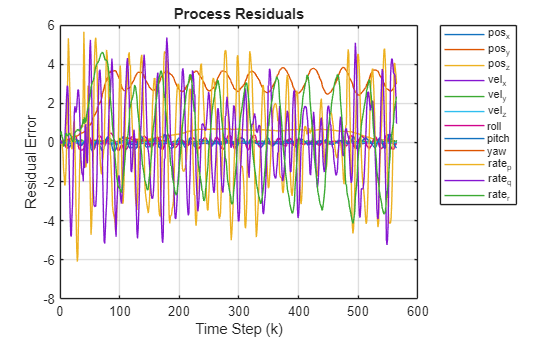

% figure;
% plot(W);
% title('Process residuals');
figure;
plot(W);
title('Process Residuals');
xlabel('Time Step (k)');
ylabel('Residual Error');

% Create labels for the 12 state variables
labels = {
    'pos_x', 'pos_y', 'pos_z', ...
    'vel_x', 'vel_y', 'vel_z', ...
    'roll', 'pitch', 'yaw', ...
    'rate_p', 'rate_q', 'rate_r'
};

legend(labels, 'Location', 'bestoutside', 'FontSize', 8);
grid on;

Check dt consistency

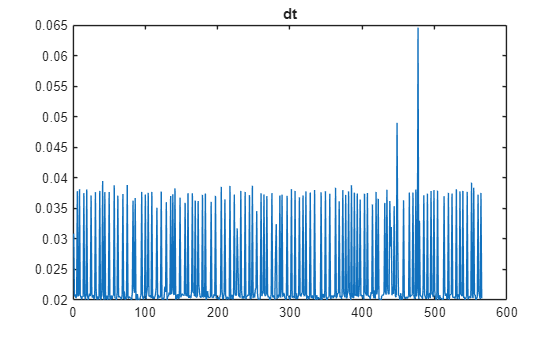

figure;
plot(data.dt_s);
title('dt');

Now Predicting NEES, NIS and K(Kalman Gain)

% Initialization for metrics
N = height(data);
nx = 12; 
P = eye(nx) * 0.1;           % Initial state covariance
x_est = X(1, :)';            % Initial state estimate
K_history = zeros(nx, nx, N); 
NIS = zeros(N-1, 1);
NEES = zeros(N-1, 1);
g_vector = [0; 0; 9.81];     % Your corrected gravity

% Measurement matrix (Direct observation of all 12 states)
H = eye(nx); 

for k = 1:N-1
    dt = data.dt_s(k);
    
    % --- 1. PREDICT (f(x)) ---
    % Use the same logic you used to find Q
    Rwb = euler_to_rot(data.odom_roll_rad(k), data.odom_pitch_rad(k), yaw(k));
    acc_body = [data.imu_accel_x(k); data.imu_accel_y(k); data.imu_accel_z(k)] * 9.81;
    acc_world = (Rwb * acc_body + g_vector) - acc_bias'; 

    x_pred = x_est; % Start with previous estimate
    x_pred(1:3)   = x_est(1:3) + x_est(4:6) * dt;    % Pos update
    x_pred(4:6)   = x_est(4:6) + acc_world * dt;     % Vel update
    x_pred(7:9)   = x_est(7:9) + x_est(10:12) * dt;  % Ori update
    x_pred(10:12) = [data.imu_gyro_x(k); data.imu_gyro_y(k); data.imu_gyro_z(k)]; % Gyro

    % State Transition Jacobian (F)
    F = eye(nx);
    F(1:3, 4:6) = eye(3) * dt; 
    F(7:9, 10:12) = eye(3) * dt;
    
    P_pred = F * P * F' + Q; % Predict covariance

    % --- 2. UPDATE ---
    z = X(k+1, :)';           % Actual measurement from Odom
    y = z - (H * x_pred);     % Innovation (Residual)
    S = H * P_pred * H' + R;  % Innovation Covariance
    
    % Kalman Gain K
    K = P_pred * H' / S;      
    K_history(:, :, k) = K;
    
    % Update State and Covariance
    x_est = x_pred + K * y;
    P = (eye(nx) - K * H) * P;

    % --- 3. COMPUTE METRICS ---
    NIS(k) = y' * (S \ y);               % Normalized Innovation Squared
    err = x_est - z;                     % Estimation Error
    NEES(k) = err' * (P \ err);          % Normalized Estimation Error Squared
end

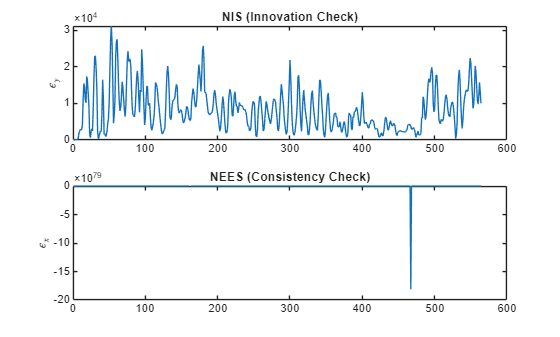


% --- PLOTTING ---
figure;
subplot(2,1,1); plot(NIS); title('NIS (Innovation Check)'); ylabel('$\epsilon_y$', 'Interpreter', 'latex');
subplot(2,1,2); plot(NEES); title('NEES (Consistency Check)'); ylabel('$\epsilon_x$', 'Interpreter', 'latex');